clear ;
close all;

load ryan2_gen_data.mat

FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

[https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets](https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets)

`Total     = Design + Nondesign`

` Design    = Training + Validation`

` Nondesign = Testing`

` Total       = Training + Nontraining`

` Nontraining = Validation + Testing`

` Overfitting: Using more ``weights and biases than necessary`

` Overtraining: Improving the ``performance of the training data at the expense of deteriorating the performance`

` on ``nontraining data`

` Training ``data subset: Used to DIRECTLY estimate weights and biases. Performance estimates are BIASED.`

` Validation ``data subset: Used to `

` (1) determine ``when overtraining an overfit net begins to occur AND `

` (2) rank ``multiple designs. `

` Performance ``estimates are SIGNIFICANTLY LESS BIASED than training data estimates.`

` Test data subset: Used to obtain UNBIASED ESTIMATES of performance on nontraining (INCLUDING UNSEEN!) data`

[https://kr.mathworks.com/help/deeplearning/ref/dividerand.html](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html)

`[`[`trainInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_1728d793-edc6-4595-8a0d-22992dffe813)`,`[`valInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_caf766f1-5912-45f0-919e-f903b9d313f4)`,`[`testInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_8e6cbc0b-a46a-4dbf-b95c-5eb6fcd46e9b)`] = dividerand(`[`Q`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_a6062bcf-a3b1-4224-9caa-fa872fae85d3)`,`[`trainRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_72c9b34e-a329-46f2-a907-39b169c6e19a)`,`[`valRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_2abef95f-2bd8-4aec-8a09-126cd5c93bcc)`,`[`testRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_f4192d38-e08b-446c-af8a-ee0cc9472af8)`)`는 나눌 목표값의 개수, 훈련에 사용할 벡터의 비율, 검증에 사용할 벡터의 비율, 테스트에 사용할 벡터의 비율을 받고, 훈련 인덱스, 검증 인덱스, 테스트 인덱스를 반환합니다

[https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html](https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html)

훈련, 테스트 및 검증의 디폴트 비율은 각각 0.7, 0.15, 0.15입니다.

[https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html)

베이즈 정규화는 함수 [`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)에 구현되어 있습니다. 다음 코드는 이 함수를 사용하여 1-20-1 신경망이 [얕은 신경망 일반화를 개선하고 과적합 방지하기](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html) 항목의 그림에 나와 있는 잡음이 있는 사인파를 근사하도록 훈련시키는 방법을 보여줍니다. ([`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)의 영향이 조기 중지로부터 격리되도록 `net.divideFcn`을 설정하여 데이터 분할이 취소되었습니다.)

`x = -1:0.05:1;`

`t = sin(2*pi*x) + 0.1*randn(size(x));`

`net = feedforwardnet(20,'trainbr');`

`net = train(net,x,t);`

xnorm = xnormall;
ynorm = ynormall;

- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainRand;
netFNN1_1.divideParam.valInd = idxValidRand;
netFNN1_1.divideParam.testInd = idxTestRand; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%tr

filterSize = 5;
numFilters = 32;
numFCN = 1;

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.36 |         0.32 |       0.0665 |       0.0510 |          0.0010 |
|      50 |          50 |       00:00:09 |         0.11 |         0.15 |       0.0057 |       0.0109 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.08 |         0.15 |       0.0034 |       0.0109 |          0.0010 |
|     150 |         150 |       00:00:13 |         0.06 |         0.15 |       0.0019 |   

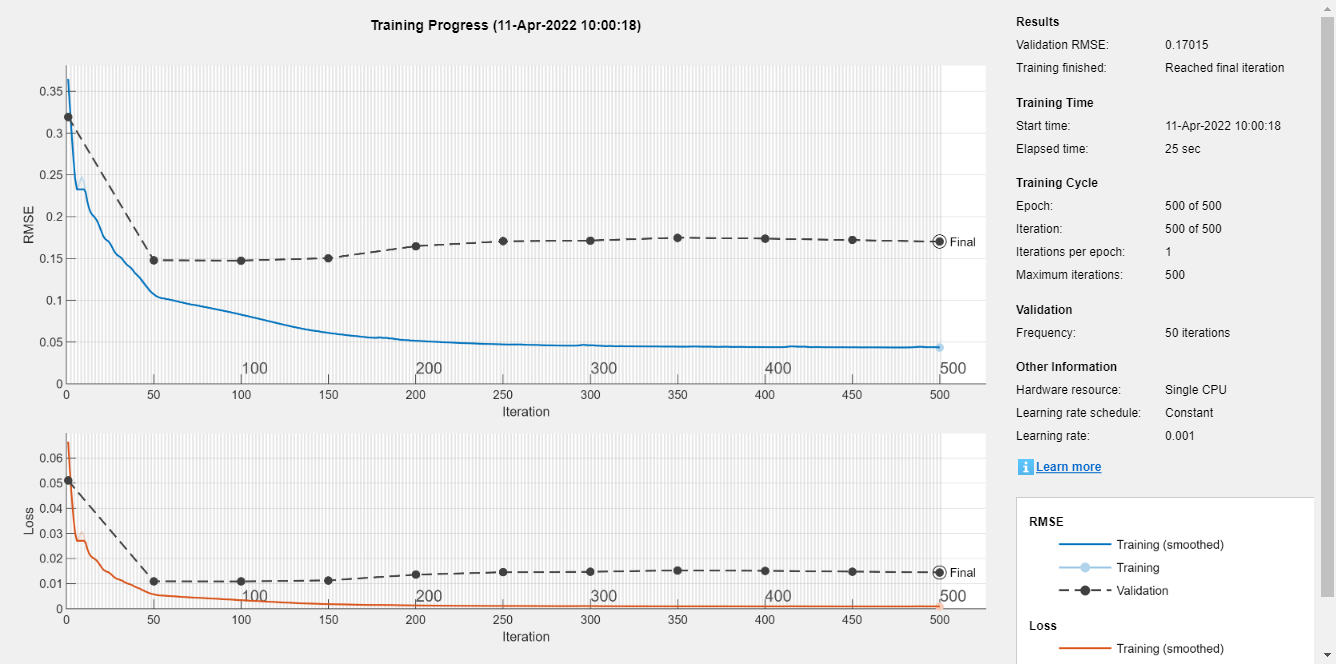

input_size = 100;
layerCNN2_1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);



%

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.34 |         0.33 |       0.0576 |       0.0535 |          0.0010 |
|      50 |          50 |       00:00:08 |         0.10 |         0.14 |       0.0046 |       0.0100 |          0.0010 |
|     100 |         100 |       00:00:10 |         0.07 |         0.13 |       0.0024 |       0.0087 |          0.0010 |
|     150 |         150 |       00:00:11 |         0.04 |         0.14 |       0.0009 |   

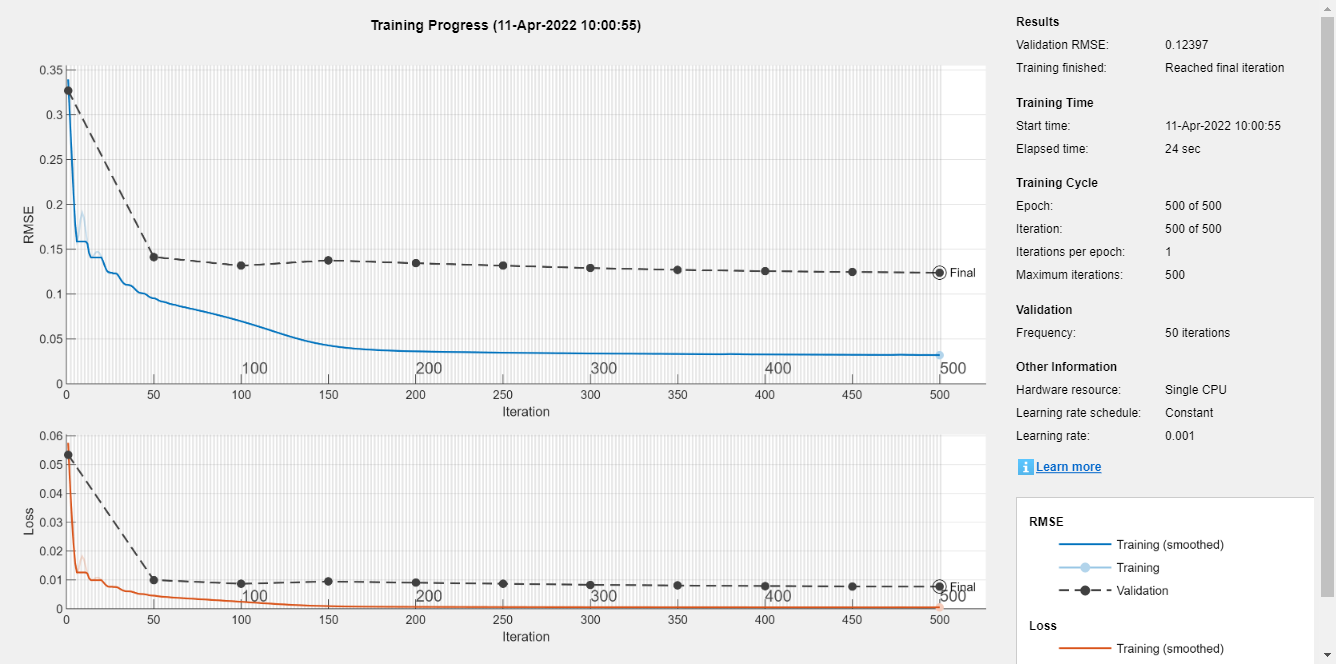

layerCNN2_2 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

[https://kr.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution1dlayer.html](https://kr.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution1dlayer.html)

[https://kr.mathworks.com/help/deeplearning/ug/sequence-classification-using-1-d-convolutions.html](https://kr.mathworks.com/help/deeplearning/ug/sequence-classification-using-1-d-convolutions.html)

Create 1-D Convolutional Layer

Create a 1-D convolutional layer with numFilters filters of width of filterSize.

matlab 2021b 부터 지원

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.39 |         0.32 |       0.0779 |       0.0527 |          0.0010 |
|      50 |          50 |       00:00:11 |         0.13 |         0.18 |       0.0089 |       0.0169 |          0.0010 |
|     100 |         100 |       00:00:14 |         0.10 |         0.16 |       0.0051 |       0.0132 |          0.0010 |
|     150 |         150 |       00:00:16 |         0.09 |         0.17 |       0.0037 |   

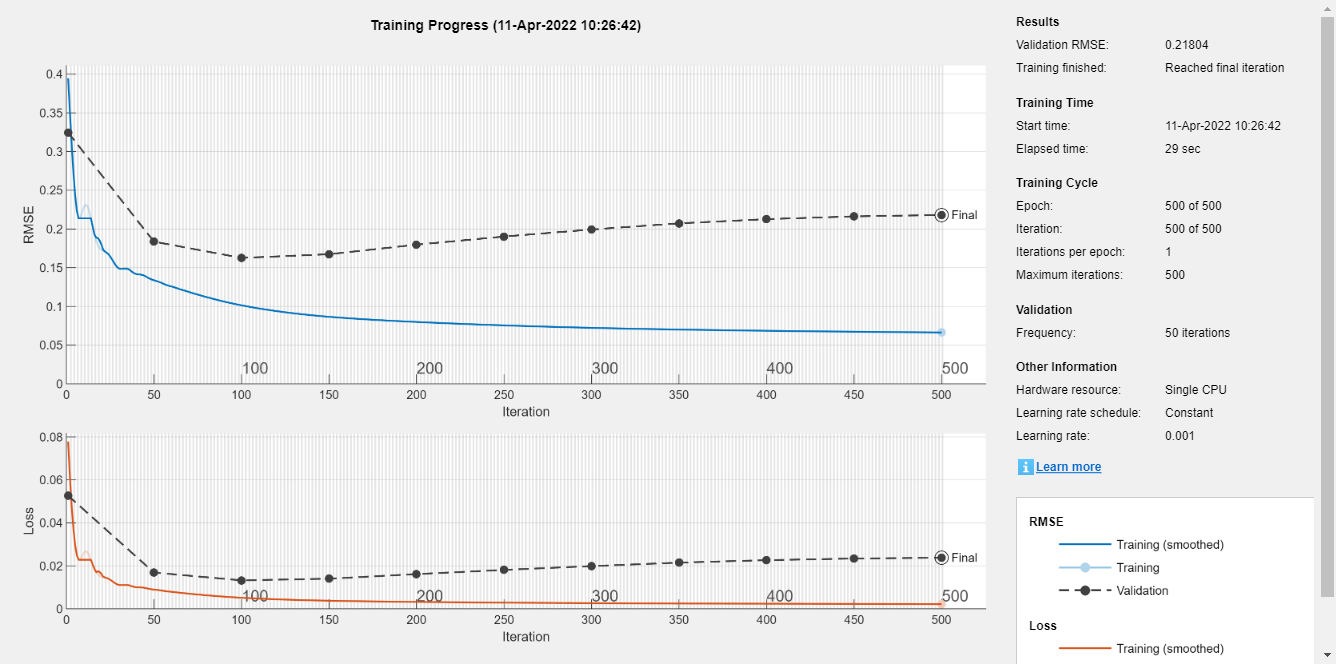



layerCNN1_1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.60 |         0.24 |       0.1773 |       0.0294 |          0.0010 |
|      50 |          50 |       00:00:13 |         0.10 |         0.15 |       0.0046 |       0.0109 |          0.0010 |
|     100 |         100 |       00:00:18 |         0.09 |         0.14 |       0.0040 |       0.0102 |          0.0010 |
|     150 |         150 |       00:00:24 |         0.09 |         0.14 |       0.0038 |   

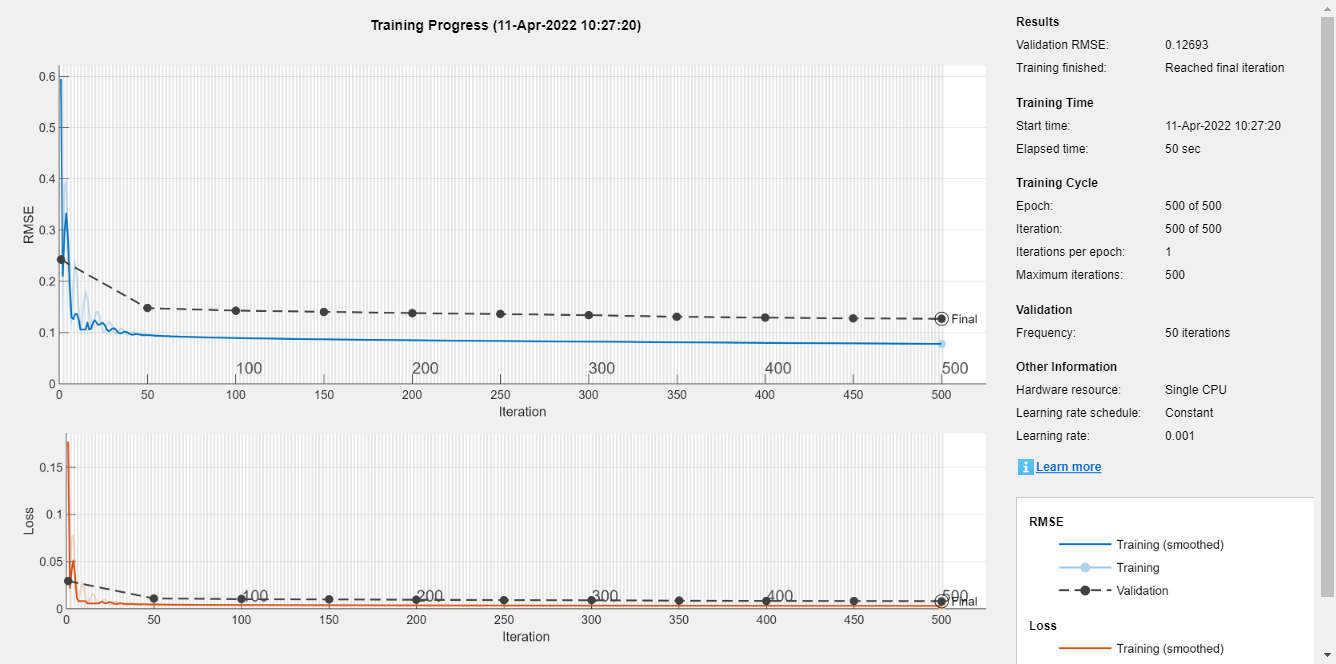



layerCNN2_3 = [ ...
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.25 |         2.80 |       0.0318 |       3.9171 |          0.0010 |
|      50 |          50 |       00:00:20 |         0.15 |         0.15 |       0.0107 |       0.0111 |          0.0010 |
|     100 |         100 |       00:00:29 |         0.13 |         0.14 |       0.0091 |       0.0093 |          0.0010 |
|     150 |         150 |       00:00:41 |         0.13 |         0.13 |       0.0085 |   

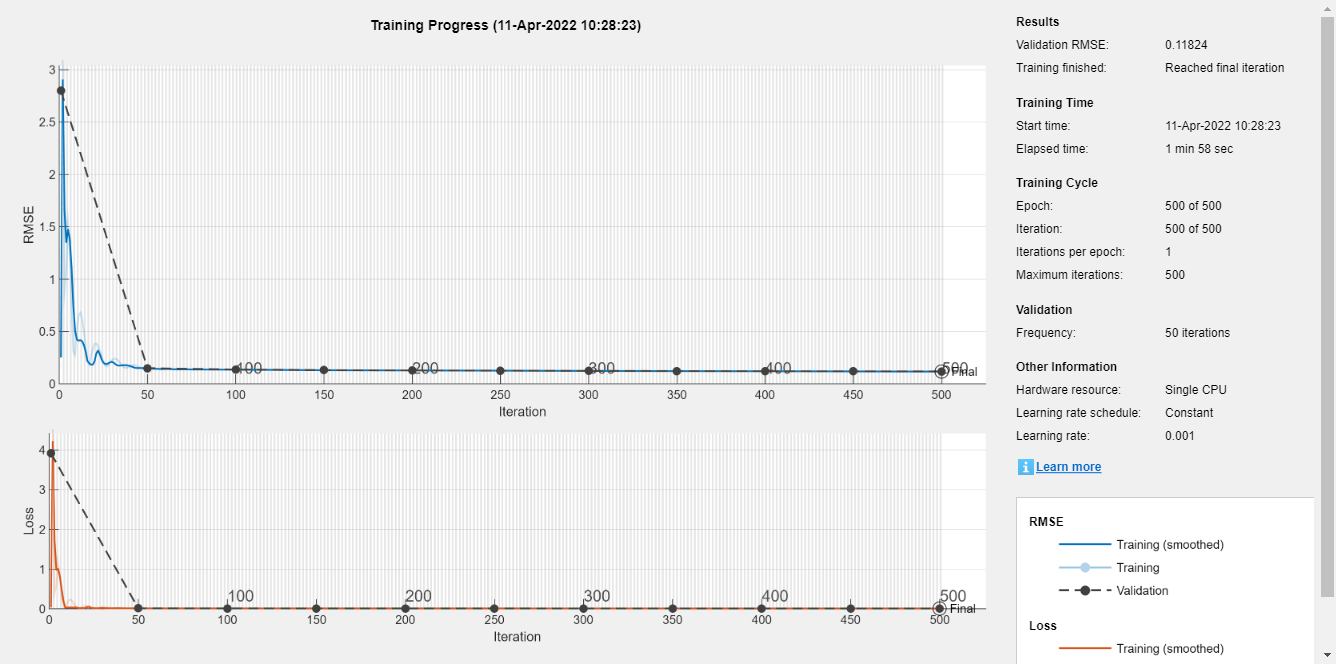


layerCNN2_4 = [ ...
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

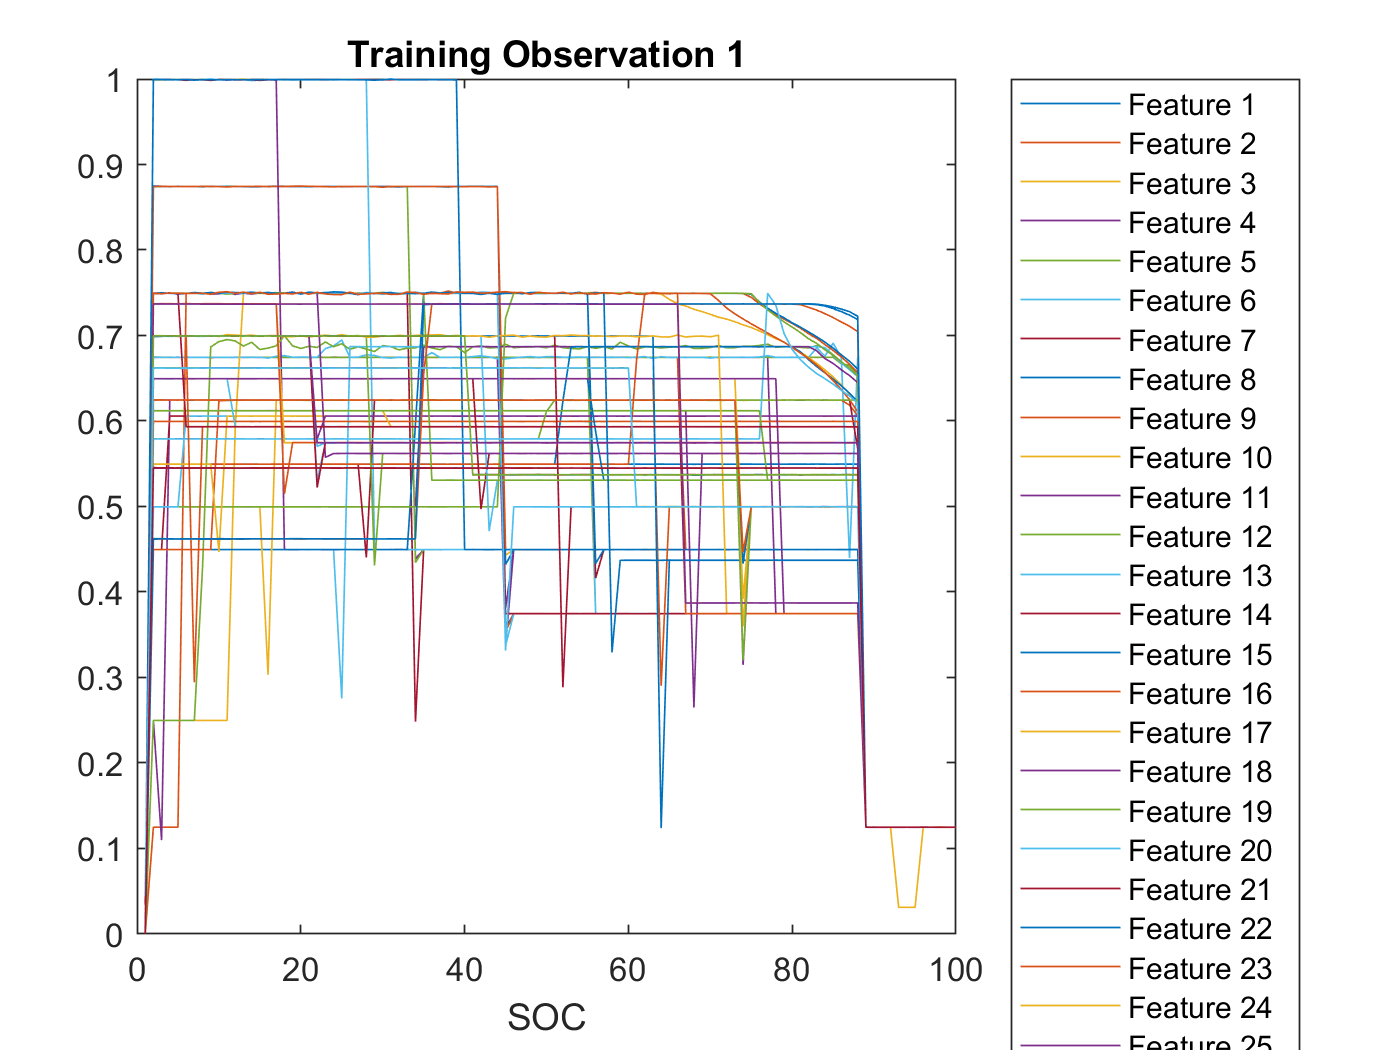

figure
plot(xnorm')
xlabel("SOC")
title("Training Observation 1")
numFeatures = size(xnorm,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")

cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end


pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
pCNN2_3 = predict(netCNN2_3, x_4d);
pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);


pCNN2_2_1  = predict(netCNN2_1  , x_4d)

pCNN2_2_1 = 12×1 single column vector
    0.2860
    0.1150
    0.1817
    0.3052
    0.0796
    0.1724
    0.1776
    0.4070
    0.3190
    0.1998


pCNN2_2_2  = predict(netCNN2_2  , x_4d)

pCNN2_2_2 = 12×1 single column vector
    0.2902
    0.1124
    0.2170
    0.6543
    0.1344
    0.1018
    0.2251
    0.3573
    0.3053
    0.2294


pCNN2_2_3  = predict(netCNN2_3  , x_4d)

pCNN2_2_3 = 12×1 single column vector
    0.2411
    0.1366
    0.1361
    0.3586
    0.1017
    0.1191
    0.4542
    0.2875
    0.3073
    0.5032


pCNN2_2_4  = predict(netCNN2_4  , x_4d)

pCNN2_2_4 = 12×1 single column vector
    0.2275
    0.1154
    0.1178
    0.1448
    0.1887
    0.2321
    0.1651
    0.3258
    0.2703
    0.3225


pCNN2_1_1  = predict(netCNN1_1  , x_4d)

pCNN2_1_1 = 12×1 single column vector
    0.2274
    0.8499
    0.1279
    0.9810
    0.0904
    0.1639
    0.1302
    0.3411
    0.4681
    0.6039



ytest = ynorm(tr.testInd, :)*yrate + ymin;
pCNN2_2_1_hat = pCNN2_2_1 * yrate + ymin;
pCNN2_2_2_hat = pCNN2_2_2 * yrate + ymin;
pCNN2_2_3_hat = pCNN2_2_3 * yrate + ymin;
pCNN2_2_4_hat = pCNN2_2_4 * yrate + ymin;
pCNN2_1_1_hat = pCNN2_1_1 * yrate + ymin;


rmse_pCNN2_2_1_hat = sqrt(mean(( ytest' - pCNN2_2_1_hat' ).^2))

rmse_pCNN2_2_1_hat = single
148.7402

rmse_pCNN2_2_2_hat = sqrt(mean(( ytest' - pCNN2_2_2_hat' ).^2))

rmse_pCNN2_2_2_hat = single
103.5702

rmse_pCNN2_2_3_hat = sqrt(mean(( ytest' - pCNN2_2_3_hat' ).^2))

rmse_pCNN2_2_3_hat = single
105.7725

rmse_pCNN2_2_4_hat = sqrt(mean(( ytest' - pCNN2_2_4_hat' ).^2))

rmse_pCNN2_2_4_hat = single
85.6212

rmse_pCNN2_1_1_hat = sqrt(mean(( ytest' - pCNN2_1_1_hat' ).^2))

rmse_pCNN2_1_1_hat = single
211.2584

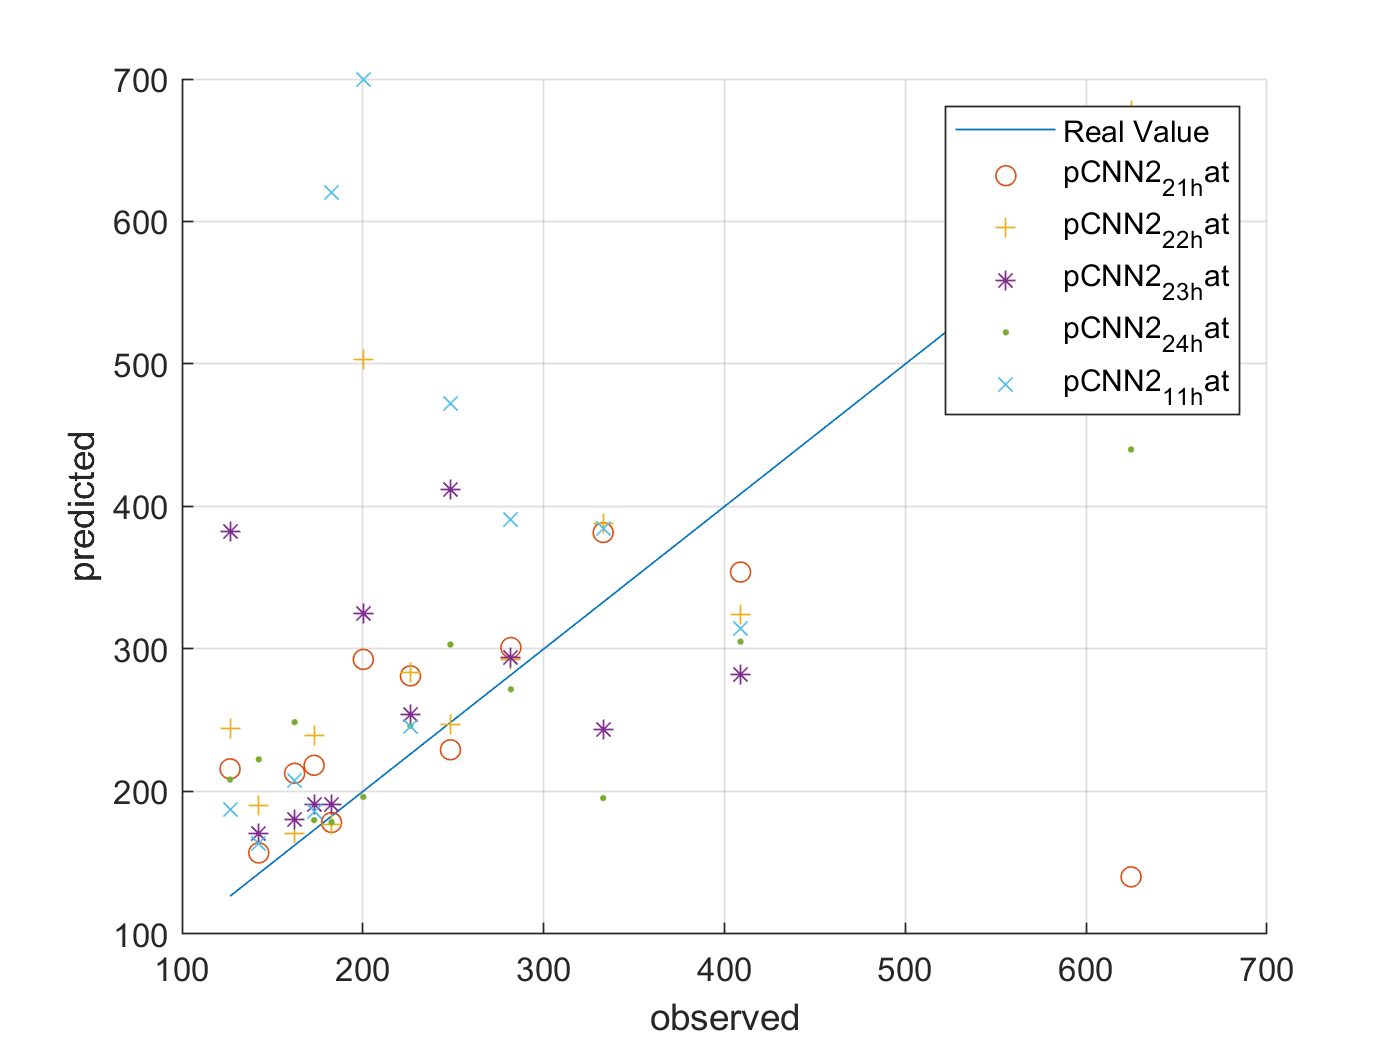




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_2_1_hat,'o')
plot(ytest,pCNN2_2_2_hat,'+')
plot(ytest,pCNN2_2_3_hat,'*')
plot(ytest,pCNN2_2_4_hat,'.')
plot(ytest,pCNN2_1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_2_1_hat', ... 
		'pCNN2_2_2_hat', ...
		'pCNN2_2_3_hat', ... 	
		'pCNN2_2_4_hat', ... 
		'pCNN2_1_1_hat')




save('ryan2_gen_data_model.mat','netCNN2_1' ,'-append')
save('ryan2_gen_data_model.mat','netCNN2_2' ,'-append')
save('ryan2_gen_data_model.mat','netCNN2_3' ,'-append')
save('ryan2_gen_data_model.mat','netCNN2_4' ,'-append')
save('ryan2_gen_data_model.mat','netCNN1_1' ,'-append')


cellx_self = num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
pCNN2_3_self = predict(netCNN2_3, x_4d_self);
pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pCNN2_1_self_hat = pCNN2_1_self * yrate + ymin;
pCNN2_2_self_hat = pCNN2_2_self * yrate + ymin;
pCNN2_3_self_hat = pCNN2_3_self * yrate + ymin;
pCNN2_4_self_hat = pCNN2_4_self * yrate + ymin;
pCNN1_1_self_hat = pCNN1_1_self * yrate + ymin;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = 1×107 single row vector
	1.0e+03 *

    0.3267    0.3043    0.3980    0.2917    0.3073    0.2987    0.3021    0.3009    0.3059    0.2917    0.3836    0.3679    0.3719    0.3738    0.3001    0.3016    0.3209    0.3010    0.2963    0.2928    0.2946    0.3022    0.3215    0.3357    0.3318    0.3442    0.3960    0.3202    0.3362    0.5636    0.6981    0.5339    0.4466    0.4200    0.4222    0.4361    0.4179    0.4164    0.4100    0.4339    0.4045    0.4136    0.3969    0.3876    0.4093    0.4339    0.4265    0.4287    0.4072    0.4193


rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = 1×107 single row vector
	1.0e+03 *

    0.2615    0.2811    0.4053    0.2506    0.2862    0.2441    0.2772    0.2748    0.2470    0.2506    0.3131    0.2980    0.3741    0.3764    0.2735    0.2762    0.3071    0.2448    0.2439    0.2453    0.2442    0.2453    0.2574    0.2689    0.2656    0.3392    0.4029    0.2565    0.2693    0.4938    0.6304    0.4636    0.3753    0.3488    0.3509    0.3648    0.3466    0.3452    0.3389    0.3626    0.3334    0.3424    0.3260    0.3169    0.3382    0.3626    0.3553    0.3574    0.3361    0.3480


rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))

rmse_pCNN2_3_self_hat = 1×107 single row vector
	1.0e+03 *

    0.1757    0.2253    0.3786    0.1770    0.2325    0.1594    0.2197    0.2163    0.1603    0.1770    0.2376    0.2197    0.3427    0.3454    0.2143    0.2184    0.2607    0.1592    0.1605    0.1658    0.1622    0.1593    0.1710    0.1846    0.1807    0.3010    0.3759    0.1699    0.1851    0.4393    0.5836    0.4069    0.3095    0.2793    0.2817    0.2976    0.2768    0.2752    0.2679    0.2951    0.2615    0.2719    0.2528    0.2421    0.2671    0.2951    0.2867    0.2892    0.2647    0.2784


rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))

rmse_pCNN2_4_self_hat = 1×107 single row vector
	1.0e+03 *

    0.2469    0.2259    0.3466    0.2051    0.2304    0.2120    0.2227    0.2207    0.2209    0.2051    0.3156    0.2970    0.3152    0.3175    0.2196    0.2219    0.2495    0.2148    0.2091    0.2054    0.2072    0.2163    0.2404    0.2581    0.2533    0.2805    0.3442    0.2389    0.2587    0.5156    0.6579    0.4836    0.3876    0.3576    0.3600    0.3758    0.3551    0.3535    0.3462    0.3733    0.3398    0.3502    0.3310    0.3202    0.3454    0.3733    0.3650    0.3675    0.3430    0.3567


rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = 1×107 single row vector
	1.0e+03 *

    0.3605    0.3254    0.4049    0.3192    0.3276    0.3300    0.3239    0.3231    0.3383    0.3192    0.4179    0.4022    0.3815    0.3832    0.3226    0.3236    0.3381    0.3327    0.3271    0.3222    0.3248    0.3342    0.3550    0.3697    0.3657    0.3574    0.4030    0.3537    0.3702    0.5958    0.7287    0.5665    0.4803    0.4540    0.4562    0.4700    0.4519    0.4505    0.4442    0.4678    0.4386    0.4477    0.4312    0.4219    0.4435    0.4678    0.4605    0.4627    0.4414    0.4533


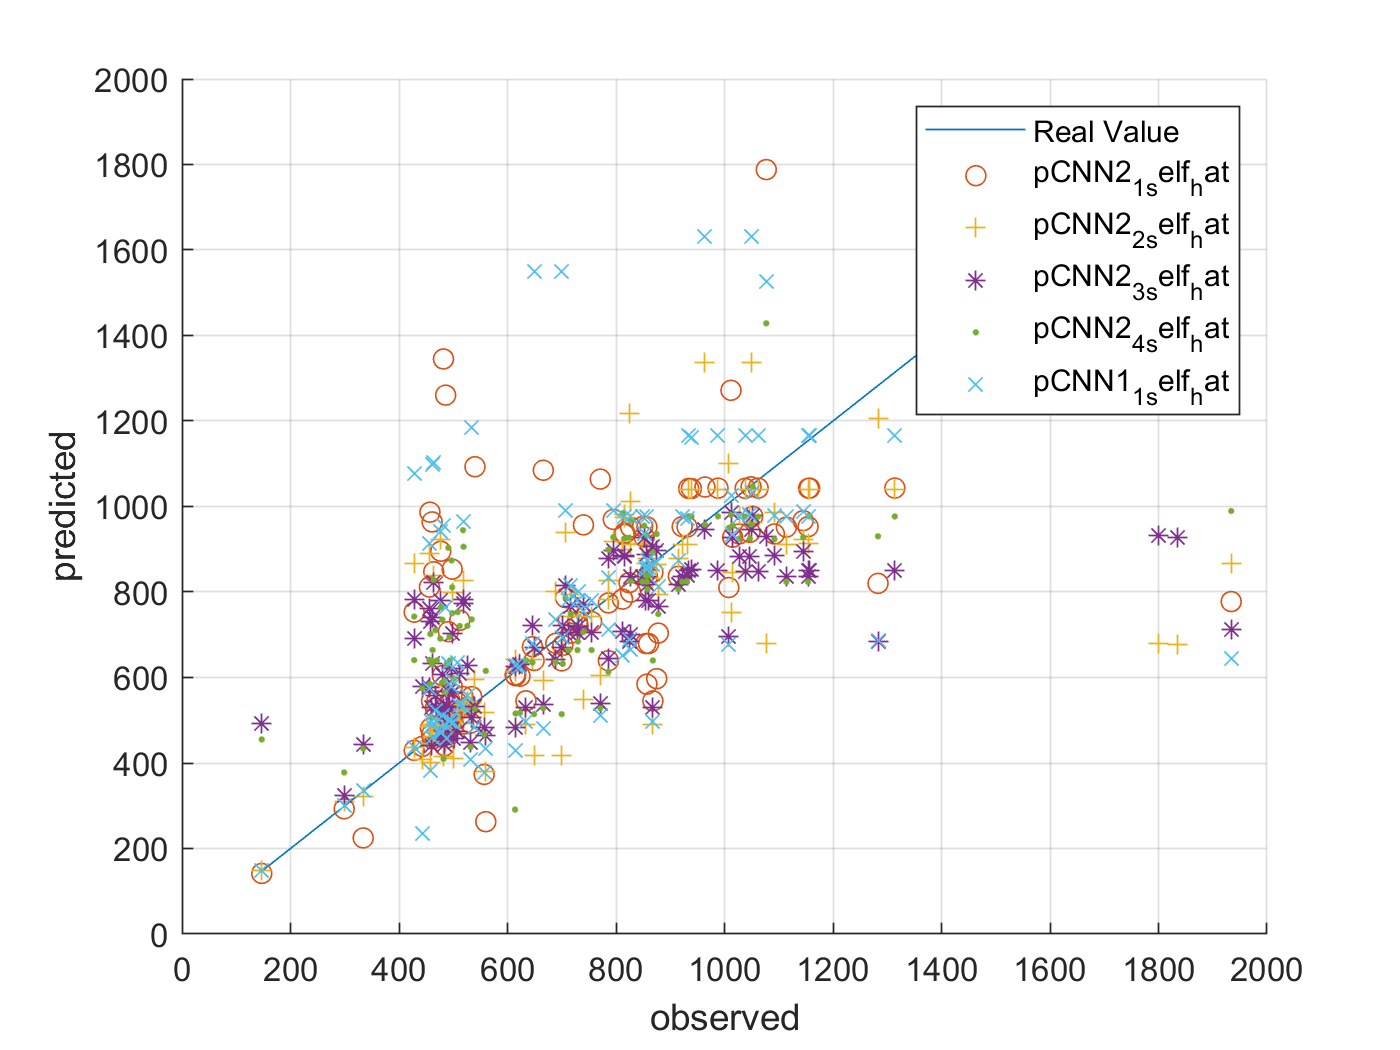




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
plot(ytrain_self,pCNN2_3_self_hat,'*')
plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN2_3_self_hat', ... 	
		'pCNN2_4_self_hat', ... 
		'pCNN1_1_self_hat')